f0 = 1;
K = 10;
Fa = 100;

a = zeros(1, K+1);
b = zeros(1, K+1);
for i = 1:K
    if rem(i,2)==0
        b(i) = 4/((i-1)*pi);
    end
end
[sinal,t] = SomaFourier(1/Fa,f0,4,a,b)

sinal =          0    0.3914    0.7337    0.9885    1.1370    1.1823    1.1474    1.0675    0.9807    0.9179    0.8959    0.9155    0.9635    1.0192    1.0617    1.0772    1.0626    1.0257    0.9815    0.9468    0.9338    0.9465    0.9791    1.0189    1.0509    1.0631    1.0509    1.0189    0.9791    0.9465    0.9338    0.9468    0.9815    1.0257    1.0626    1.0772    1.0617    1.0192    0.9635    0.9155    0.8959    0.9179    0.9807    1.0675    1.1474    1.1823    1.1370    0.9885    0.7337    0.3914


t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


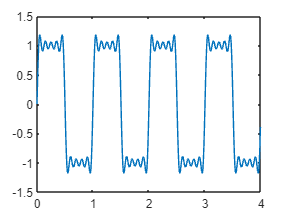


plot(t,sinal)

3.

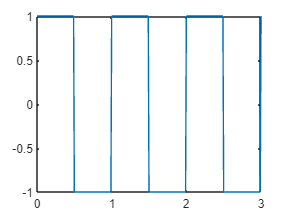

f0 = 1;
T0 = 1/f0;
K = 10;
Fa = 100;

t = 0 : 1/Fa : 4-1;
x = square(2*pi*1*t);
plot(t,x)


[a1,b1] = CalcCoef(1/Fa,T0,x,K)

a1 =          0    0.0400    0.0000    0.0400   -0.0000    0.0400   -0.0000    0.0400    0.0000    0.0400


b1 =          0    1.2728   -0.0000    0.4232   -0.0000    0.2526   -0.0000    0.1789    0.0000    0.1377


4.

f0 = 1;
T0 = 1/f0;
K = 10;
Fa = 100;

t = 0 : 1/Fa : 4;
x = 4 * abs(mod(t * f0 - 0.25, 1) - 0.5) - 1;
[a2,b2] = CalcCoef(1/Fa,T0,x,K)

a2 = 1.0e-15 *

    0.0044    0.0978    0.0321   -0.0208   -0.1209    0.1102   -0.1513   -0.0316    0.2134    0.1291


b2 =          0    0.8108   -0.0000   -0.0903    0.0000    0.0327   -0.0000   -0.0168    0.0000    0.0103


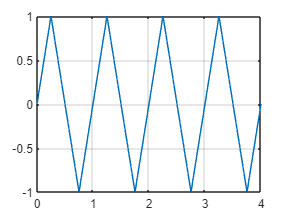


plot(t,x)
grid on


[sinal,t] = SomaFourier(1/Fa,f0,4,a2,b2)

sinal =     0.0000    0.0424    0.0839    0.1239    0.1623    0.1997    0.2372    0.2756    0.3158    0.3577    0.4006    0.4436    0.4854    0.5251    0.5625    0.5985    0.6345    0.6722    0.7131    0.7576    0.8046    0.8516    0.8949    0.9300    0.9529    0.9609    0.9529    0.9300    0.8949    0.8516    0.8046    0.7576    0.7131    0.6722    0.6345    0.5985    0.5625    0.5251    0.4854    0.4436    0.4006    0.3577    0.3158    0.2756    0.2372    0.1997    0.1623    0.1239    0.0839    0.0424


t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


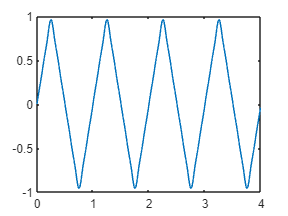

plot(t,sinal)